GSN_st.name='GSN'; 
GSN_st.lat=33.2799987793;
GSN_st.lon=126.1699981689;
GSN_st.alt=72;
GSN_st.env='coast';
GSN_st.footp='RB';


GSN_rd=read_betsy('gsn_2008_2018',GSN_st.name);
% GSN_rd.U0_S(GSN_rd.U0_S==999.9)=NaN;
% GSN_rd.Uu0_S(GSN_rd.Uu0_S==999.9)=NaN;
% GSN_rd.U1_S(GSN_rd.U1_S==999.9)=NaN;
% GSN_rd.Uu1_S(GSN_rd.Uu1_S==999.9)=NaN;
% figure;
% plot(GSN_rd.Time, GSN_rd.U0_S,'.b');
% hold on;
% plot(GSN_rd.Time, GSN_rd.Uu0_S,'.r');


datevec(GSN_rd.Time(1))

ans =         2008           1           2           0           0           0

datevec(GSN_rd.Time(end))

ans =         2019           1           1           0           0           0

 prctile(GSN_rd.U0_S11,[5 50 95])

ans =    14.2150   29.9000   64.0000

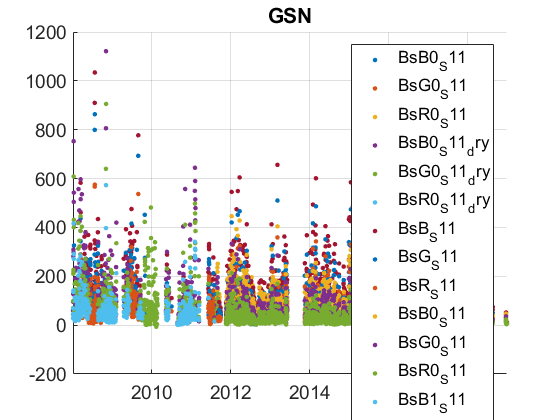

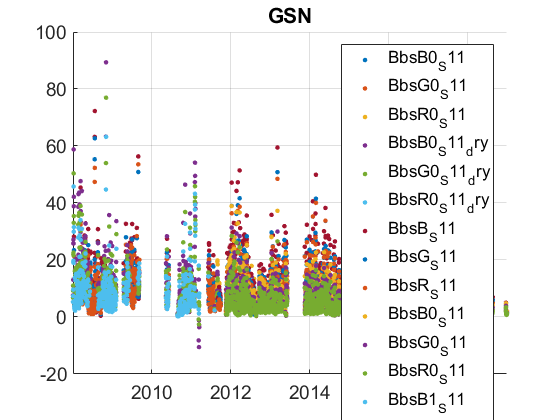

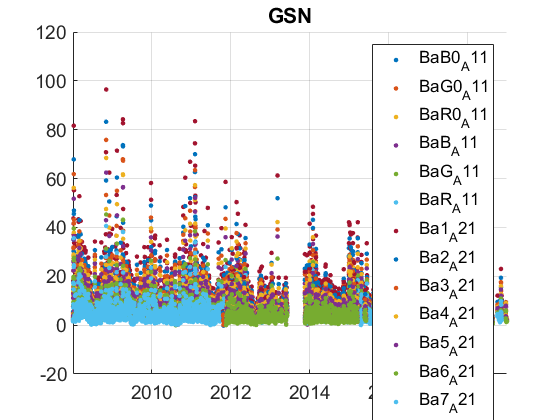

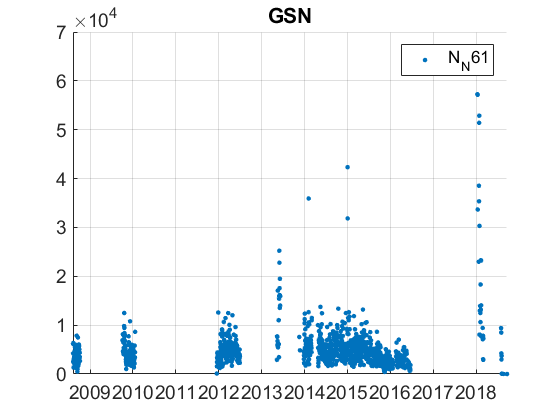

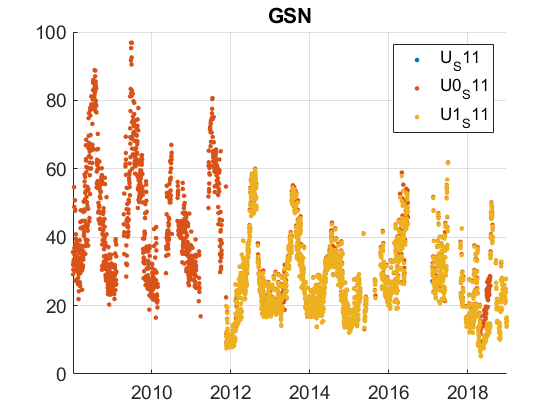

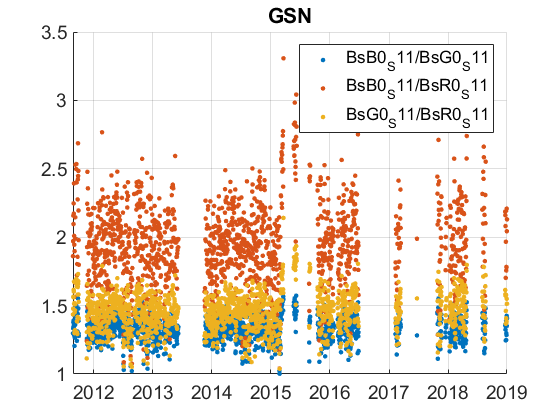

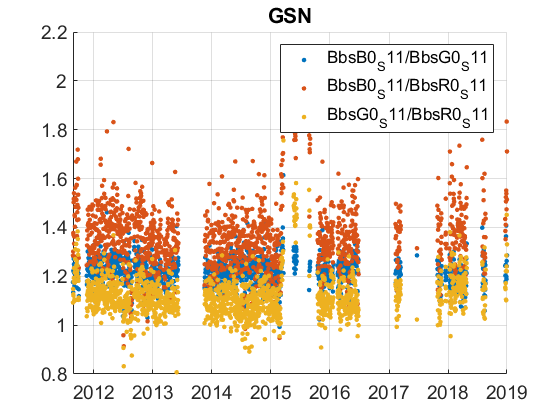

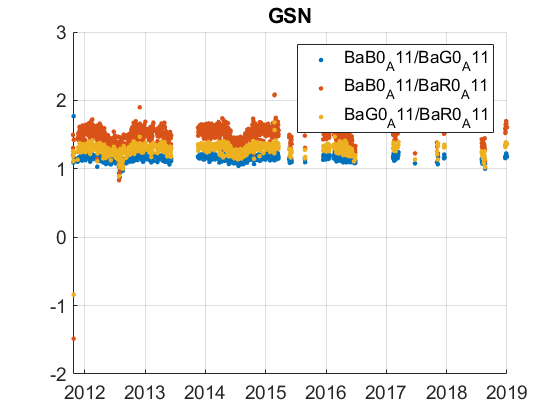

 %prctile(GSN_rd.U1_S11,[5 50 95])
% prctile(GSN_rd.Uu1_S,[5 50 95])
plotFigControl(GSN_rd,GSN_st.name);

% 2 size cut, ok
% sc: ok, no negatives, no clear seasonal cycle
%clear seasonal cycle of the abs exponent with max in winter

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
GSN_cal=compute_exp_SSA(GSN_rd,lambdaSC, lambdaAE);

SCexclus = 1

ans = 1

ans = 1189

ans = 0

SCexclus = 1

ans = 1

ans = 1189

ans = 0

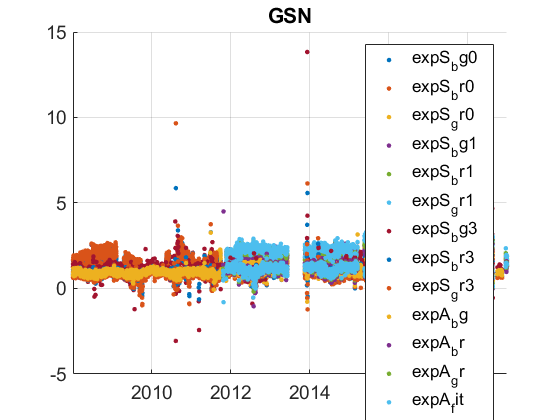

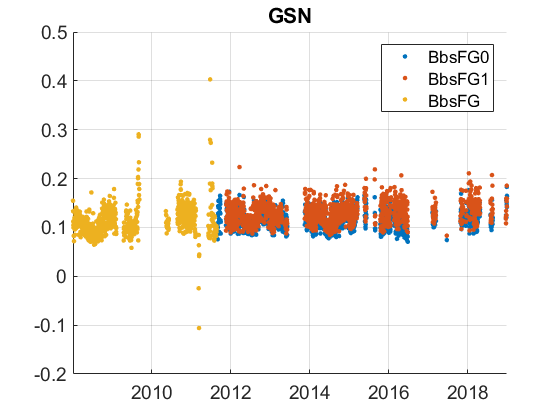

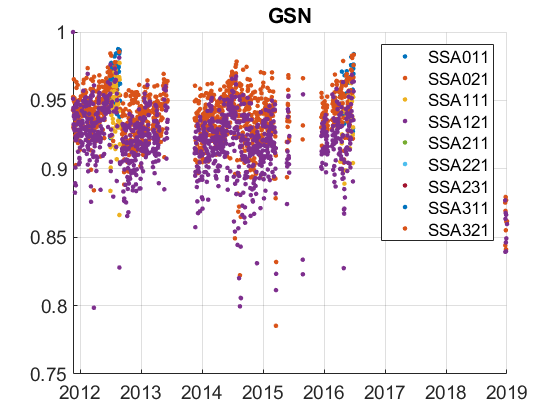

plotFigControl_cal(GSN_cal, GSN_st.name);

%Questions:
%problems:

%Size cut: which is the size cut from 2008 to mid-2011 ? TSP ? Can we consider one time series with the first GSN_tr and either PM10 or PM1 ?

%scat: there is a lot of holes: are they real holes or GSN_trbank problems ?
%scat: GSN_tr in the second part of 2012 and of 2018 are much lower than the other: are they right ?
%scat exponent: it is quite high in winter 2008-2009, in september 2010 and in May 2015. This does not seems to be a real seasonality. Do you have any exaplanation?
% backscatter fraction: are the GSN_tr in September 2009, March 2011 and June 2011 outliers that should be removed ?

%abs: the AE time series is much longer and more complete than the PSAP one. Is there really no AE GSN_tr from November 2012 to November 2013, at the end of 2016 and 2017 ?
%abs: half of 2013 could be gained if PSAP and AE are homoegenized. The best accordance seems to be between PSAP PM10 red and AE 950 nm.

%SSA: the last points in 2018 are too low due to the too low scat values.

GSN_tr=GSN_rd;
GSN_tr.y=year(GSN_tr.Time);
% begin at the beginning of a year:2008
%end: 2015 (too much problem thereafter: typhoon, low GSN_tr coverage
P=timerange('2008-01-01','2016-01-01');
GSN_tr=GSN_tr(P,:);

% PM1: 2012-2015: too short, not to analyse
%abs: use AE31 also only until end of 2015.
names=fieldnames(GSN_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) |  contains(names,["Q";"X";"B1_";"G1_";"R1_";"B0_A";"G0_A";"R0_A"]);
N=names(c);
for i=1:length(N)
    GSN_tr.(N{i})=[];
end


%fragmentation issue due to size cut: seems to be TSP and then 2 size cuts. Do one time seris TSP-PM10
GSN_tr.BsB0_S11=sum([GSN_tr.BsB_S11 GSN_tr.BsB0_S11],2,'omitnan');
indz=GSN_tr.BsB0_S11==0;
GSN_tr.BsB0_S11(indz)=NaN;
GSN_tr.BsG0_S11=sum([GSN_tr.BsG_S11 GSN_tr.BsG0_S11],2,'omitnan');
indz=GSN_tr.BsG0_S11==0;
GSN_tr.BsG0_S11(indz)=NaN;
GSN_tr.BsR0_S11=sum([GSN_tr.BsR_S11 GSN_tr.BsR0_S11],2,'omitnan');
indz=GSN_tr.BsR0_S11==0;
GSN_tr.BsR0_S11(indz)=NaN;

GSN_tr.BbsB0_S11=sum([GSN_tr.BbsB_S11 GSN_tr.BbsB0_S11],2,'omitnan');
indz=GSN_tr.BbsB0_S11==0;
GSN_tr.BbsB0_S11(indz)=NaN;
GSN_tr.BbsG0_S11=sum([GSN_tr.BbsG_S11 GSN_tr.BbsG0_S11],2,'omitnan');
indz=GSN_tr.BbsG0_S11==0;
GSN_tr.BbsG0_S11(indz)=NaN;
GSN_tr.BbsR0_S11=sum([GSN_tr.BbsR_S11 GSN_tr.BbsR0_S11],2,'omitnan');
indz=GSN_tr.BbsR0_S11==0;
GSN_tr.BbsR0_S11(indz)=NaN;

GSN_tr.BsB0_S11_dry=sum([GSN_tr.BsB_S11_dry GSN_tr.BsB0_S11_dry],2,'omitnan');
indz=GSN_tr.BsB0_S11_dry==0;
GSN_tr.BsB0_S11_dry(indz)=NaN;
GSN_tr.BsG0_S11_dry=sum([GSN_tr.BsG_S11_dry GSN_tr.BsG0_S11_dry],2,'omitnan');
indz=GSN_tr.BsG0_S11_dry==0;
GSN_tr.BsG0_S11_dry(indz)=NaN;
GSN_tr.BsR0_S11_dry=sum([GSN_tr.BsR_S11_dry GSN_tr.BsR0_S11_dry],2,'omitnan');
indz=GSN_tr.BsR0_S11_dry==0;
GSN_tr.BsR0_S11_dry(indz)=NaN;

GSN_tr.BbsB0_S11_dry=sum([GSN_tr.BbsB_S11_dry GSN_tr.BbsB0_S11_dry],2,'omitnan');
indz=GSN_tr.BbsB0_S11_dry==0;
GSN_tr.BbsB0_S11_dry(indz)=NaN;
GSN_tr.BbsG0_S11_dry=sum([GSN_tr.BbsG_S11_dry GSN_tr.BbsG0_S11_dry],2,'omitnan');
indz=GSN_tr.BbsG0_S11_dry==0;
GSN_tr.BbsG0_S11_dry(indz)=NaN;
GSN_tr.BbsR0_S11_dry=sum([GSN_tr.BbsR_S11_dry GSN_tr.BbsR0_S11_dry],2,'omitnan');
indz=GSN_tr.BbsR0_S11_dry==0;
GSN_tr.BbsR0_S11_dry(indz)=NaN;
%BaB BaG and BaR have no GSN_tr: delete
%BsB_S etc to delete
names=fieldnames(GSN_tr);
c1=  contains(names,["B_S";"G_S";"R_S";"U_S";"_A11"]);
N=names(c1);
for i=1:length(N)
    GSN_tr.(N{i})=[];
end


GSN_cal2=timetable(GSN_tr.Time);
%GSN_cal2=compute_exp_SSA(GSN_tr,lambdaSC, lambdaAE);
GSN_cal2.SSA0G=GSN_tr.BsG0_S11./(GSN_tr.BsG0_S11+GSN_tr.Ba3_A21);

GSN_cal2.SSA0G_dry=GSN_tr.BsG0_S11_dry./(GSN_tr.BsG0_S11_dry+GSN_tr.Ba3_A21);
GSN_cal2.BbsFG0=GSN_tr.BbsG0_S11./GSN_tr.BsG0_S11;
GSN_cal2.BbsFG0_dry=GSN_tr.BbsG0_S11_dry./GSN_tr.BsG0_S11_dry;
GSN_cal2.expS_bg0=real(-log(GSN_tr.BsB0_S11./GSN_tr.BsG0_S11)/log(lambdaSC(1)/lambdaSC(2)));
GSN_cal2.expS_bg0_dry=real(-log(GSN_tr.BsB0_S11_dry./GSN_tr.BsG0_S11_dry)/log(lambdaSC(1)/lambdaSC(2)));
%abs exp: the AE fit has less outliers
all_Abs=[GSN_tr.Ba1_A21 GSN_tr.Ba2_A21 GSN_tr.Ba3_A21 GSN_tr.Ba4_A21 GSN_tr.Ba5_A21 GSN_tr.Ba6_A21 GSN_tr.Ba7_A21];
        GSN_cal2.expA_fit=Exp_AE_nan_regr(all_Abs);

SCexclus = 1

ans = 1

ans = 487

ans = 0


%expS: is calculated use BG (problem with R)
% % GSN_cal2.expS_bg3=[];
% % GSN_cal2.expS_gr3=[];
% % GSN_cal2.expS_br3=[];
% % GSN_cal2.expS_gr2=[];
% % GSN_cal2.expS_br2=[];
% % GSN_cal2.expA_bg=[];
% % GSN_cal2.expA_br=[];
% % GSN_cal2.expA_gr=[];
% % GSN_cal2.BbsFG2=[];
GSN_tr=outerjoin(GSN_tr, GSN_cal2);

%compute trend only on green
GSN_tr.BsB0_S11=[];
GSN_tr.BsB0_S11_dry=[];
GSN_tr.BsR0_S11=[];
GSN_tr.BsR0_S11_dry=[];
GSN_tr.BbsB0_S11=[];
GSN_tr.BbsB0_S11_dry=[];
GSN_tr.BbsR0_S11=[];
GSN_tr.BbsR0_S11_dry=[];

GSN_tr.Ba1_A21=[];
GSN_tr.Ba2_A21=[];
GSN_tr.Ba4_A21=[];
GSN_tr.Ba5_A21=[];
GSN_tr.Ba6_A21=[];
GSN_tr.Ba7_A21=[];


%after trend analysis, decide if trend or only dlm should be used!!
GSN_result= all_trend_STN(GSN_tr,GSN_st); 

GSN_result_D=GSN_result;